# Reading and extraction of Feature points

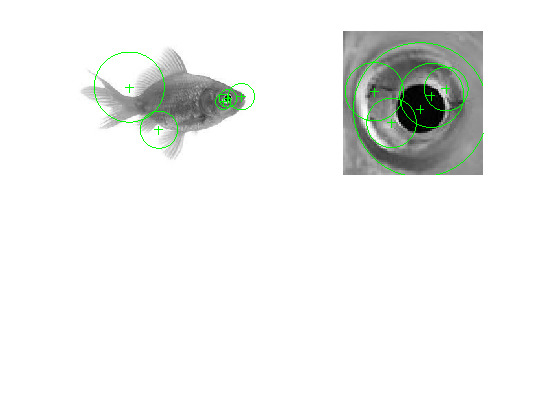

I1 = imread("Goldfish-1.jpg");
I2 = imread("Goldfish_eye.jpg");
IG1 = rgb2gray(I1);
IG2 = rgb2gray(I2);
Ipts1 = detectSURFFeatures(IG1);
Ipts2 = detectSURFFeatures(IG2);
[Iref1_features,  Iref1_validPts] = extractFeatures(IG1,  Ipts1);
[Iref2_features,  Iref2_validPts] = extractFeatures(IG2,  Ipts2);
subplot(2,2,1);
imshow(IG1); hold on;
plot(Ipts1.selectStrongest(5));
subplot(2,2,2);
imshow(IG2); hold on;
plot(Ipts2.selectStrongest(5));

## Visualisation

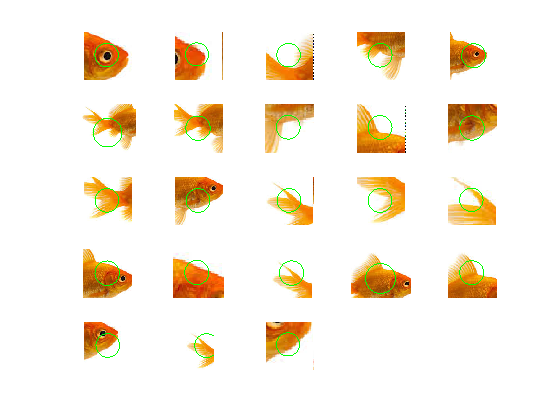

figure;
subplot(5,5,3); title('First 25 Features');
for i=1:23
    scale = I_pts(i).Scale;
    image = imcrop(I1,[Ipts1(i).Location-10*scale 20*scale 20*scale]);
    subplot(5,5,i);
    imshow(image);
    hold on;
    rectangle('Position',[5*scale 5*scale 10*scale 10*scale],'Curvature',1,'EdgeColor','g');
end

## Comparism

index_pairs = matchFeatures(Iref1_features, Iref2_features);
matchedPoints1 = Iref1_validPts(index_pairs(:,1),:).Location;
matchedPoints2 = Iref2_validPts(index_pairs(:,2),:).Location;
figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,'montage');

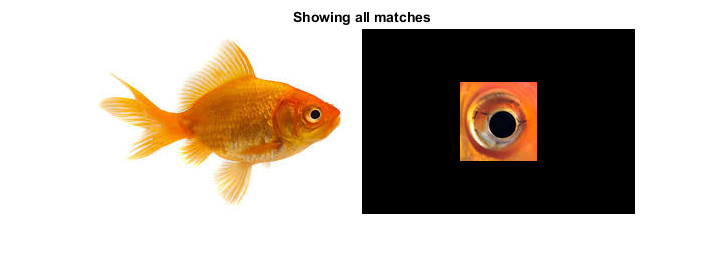

title('Showing all matches');